# Create a Current Weather App

For a more detailed overview of using App Designer, you can take the free 1 hour [App Building Onramp](https://matlabacademy.mathworks.com/details/app-building-onramp/orab).

## Design the User Interface

First, open App Designer by running the following code:

appdesigner  

This will come up in a new window. Arrange your windows so you can see these instructions and the App Designer at the same time. You should select "Blank App"

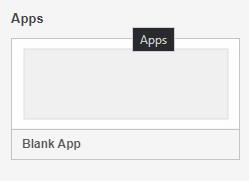

**Step 1:** Add a Gauge (linear) component to the app canvas.

In the "Component Library", search for "gauge" and add a "Gauge (linear)" to the blank canvas by clicking and dragging it into the position you want. 

**Step 2: **Set the parameters for the gauge.

On the right in the "Component Browser", set the Label to `Humidity (%)`. The default values for the other parameters work well. Note that this will automatically change the name of the component to `app.HumidityGauge`.

**Step 3: **Add a "Button" to control calling the API.Give it a name that makes sense to you like "Update" or "Call the API" or "Gather Data". 

**Step 4: **Add a "List Box" to control which city's information will be queried. Update the label to "City" and the Items to a list, one per line, of the cities you want available. The demonstration code uses:

### Save Your Work!

Before you go any farther, make sure that you have saved your work. A good option is `CurrentWeatherApp.mlapp` in the `Apps` folder. In Design View, your app should look something like:

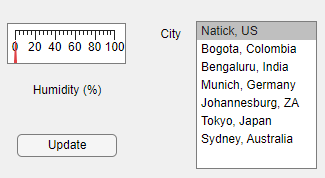

## Design the Code

Notice that the gauge exists to visualize the current value of the humidity as identified by calls to the weather API. The button and the list box, however, are intended to be elements that the user will interact with. 

### Add a Callback on the Button

User interaction is coded with functions known as "Callbacks". When a user interacts with an element of the app in a specified way, a callback function will execute. You can set up a callback on each of the required elements by right-clicking on the component and selecting "Callbacks" $\rightarrow$ "Add <default name> callback" from the context menu. For the Button, that will look something like:

open AddCallbackFromContextMenu.mlx  

Note that creating the callback this way also switched our view from Design View to Code View. 

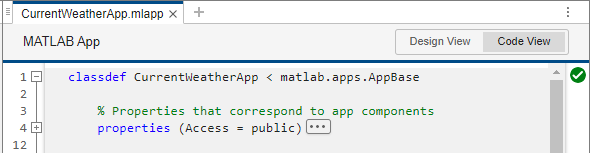

#### UpdateButtonPushed

To minimize the API calls, the query will only be made when the "Update" button is pushed. Therefore, the update button callback needs to identify the city, make the API call, and then extract and present the results.

The code for `UpdateButtonPushed` is: 

First: check what city is requested in the list box and determine the corresponding latitude and longitude. While we identify the index by the selection in the CityList

Next, set up the Python code and run it

- extract the relevant results and add the values to the display

### Try Running the App

Click the Run button () in the Editor tab of the App Designer Toolstrip. Select a city and click the Update button. The humidity gauge should register the relevant value. If it doesn't, can you figure out why? Use debugging skills from [Debugging.mlx](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Programming-Structuring-Code&project=StructuringCode.prj&file=Debugging.mlx) in [Programming: Structuring Code](https://github.com/MathWorks-Teaching-Resources/Programming-Structuring-Code).

## With the Basics Working, Add Additional Details

With a minimal viable product, now you can improve on your app. 

### Present More Information

         1. Go back to the Component library and add a Label with the text "The current city is: "

         2. Add a second Label with the text "none". In the Component Browser, rename the component from `app.noneLabel` to `app.CityLabel` to better indicate how it will be used. The value starts at "none" because there is no city information being displayed. As we update the display, we will also update the text of this label. You may want to increase the size or set the FontWeight to bold. In the `UpdateButtonPushed` callback, add a line to update the label on the display:

          3. In the "Component Library", search for "gauge" and add two copies of "Gauge" to the app. One of these will track temperature and one will track barometric pressure.

open AddMultipleComponentsToApp.mlx  

Select each gauge in turn in the MATLAB App window and update their labels to be "Temperature" and "Pressure (mmHg)", respectively. Note that this will also update their reference names in the Component Browser from `app.Gauge` and `app.Gauge2` to `app.TemperatureGauge` and `app.PressuremmHgGauge`. Change the Limits for the pressure gauge to a reasonable range of values for atmospheric pressure in `mmHG`, the demo app uses `740,780`. Set the limits for the temperature gauge to a reasonable range of values for your cities in Celsius. The demo app uses `-40,50.`

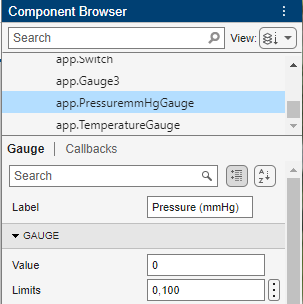

** Exercise 1. **Add the necessary code to the `UpdateButtonPushed` callback to present this data. Remember that you worked through converting the pressure already in [`CheckingTheWeather`](matlab:open('./CheckingTheWeather.mlx')). What are the units of the [temperature](https://openweathermap.org/current)? What were you expecting? How can you control that?

ShowHelpEx1  

### Improve the Design the Code

#### Defining Properties

As the design gets more complicated, we need to create some variables in the app that will be visible to every function. Such variables are called properties. In this app, most of these properties are related to components and have already been defined by the constructions that we did in the design view such as `app.HumidityGauge` or `app.UpdateButton`. You can view this set of properties in Code View at the very top of the file by clicking on the three dots to expand the code, or the + next to line 4. We can define additional properties as well to store values that we may not need to change very often or that we plan to access from different functions.

open AddProperty.mlx  

First, let's create an `apiKey` property that we only want to load once and then use throughout. We can also create a `unitChoice` property to allow the user to select a system of units. The default value of `unitChoice` will be `metric`.

To use these properties, we will need to modify some of the callback functions in this app.

### Add Additional Callbacks

#### startupFcn

Before we can think about resetting values, we need to worry about setting values in the first place! Add a default callback function to the app itself. It will be called `startupFcn`. Make it do the following:

- Make sure that Python is loaded

- Make sure that an API key is loaded

- Initialize the values of the gauges

** Exercise 2.** 

- Remove the reading of the API key from the `UpdateButtonPushed` callback.

- Update the API call in `UpdateButtonPushed` to include both property values.

### Writing Functions

There are other simplifications that can be made to the `UpdateButtonPushed` callback such as writing additional helper functions. 

open AddFunction.mlx  

Add a function called `LookupCoordinates` that will identify the latitude and longitude of the selected city.

** Exercise 3. **Replace the relevant code in `UpdateButtonPushed` with a call to `LookupCoordinates`. Note that the first argument of any function within an app will always be `app`. This is what allows access to all of the properties and functions defined in the app. 

### Offer More Control

Add a "Switch" to control whether the temperature is displayed in Celsius or Fahrenheit. Change the Items to C, F (and the default Value to C). 

#### Add a Callback on the Switch

Another way you can set up a callback on an element is by selecting "Callbacks" in the Component Browser and then accepting the default name for a new callback in each case. For the Switch, that will look something like:

open AddCallbackInComponentBrowser.mlx  

The code you want for the switch callback is:

Note that App Designer will still define the function signature for you, so you only need to write the body of the function, but by creating the callback through this method you will need to locate the new function yourself in Code View.

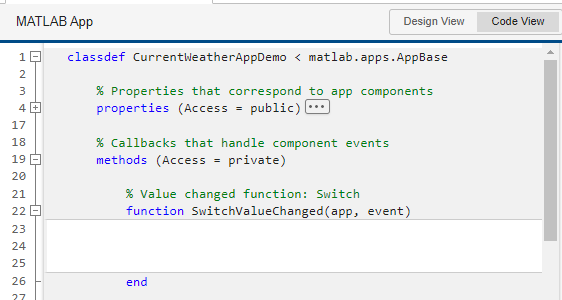

## Test the App

Run the app by using the run button in App Designer or by typing the name of your app at the command line:

## Further Practice

- Add a switch or dropdown to allow the user to control the units of pressure that will be displayed.

- Add another label and use it to display the verbal description of the weather.

- Add additional thermometers to display the high and low temperatures for the day.

You can add all sorts of additional bells and whistles to your app. Here is another possible approach that includes more of the information returned by the API related to the current time, sunrise, and sunset. 

WeatherDisplay  

function ShowHelpEx1
disp("Did you notice that the pyrun command is using ""standard"" units?")
disp("Did you use symunits to convert the pressure from hPa to mmHg?")
disp("Did you separate the new pressure value from the symbolic unit?")
disp("Did you convert the pressure value back to a double?")
end